% Bauderate: 50
% Symbolbreite T = 20msec
clear
close  all;
f_symbol = 50

f_symbol = 50

T_symbol = 1 / f_symbol

T_symbol = 0.0200

f_sample = 2.1 * f_symbol

f_sample = 105

T_sample = 1 / f_sample

T_sample = 0.0095

## Rechteckimpuls

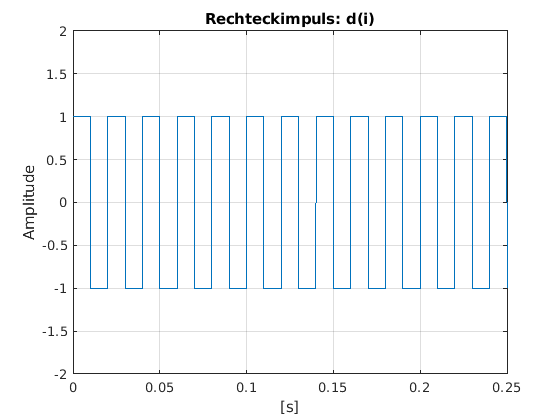

% Signallänge 10s
t = 0:T_sample/400:10;
w_symbol = 2*pi*f_symbol;
d_i = square(w_symbol*t);
figure(1)
plot(t, d_i)
title('Rechteckimpuls: d(i)')
grid on
ylim([-2 2])
xlim([0 0.25])
xlabel('[s]')
ylabel(['Amplitude'])

## Anfangsphase phi(iT)

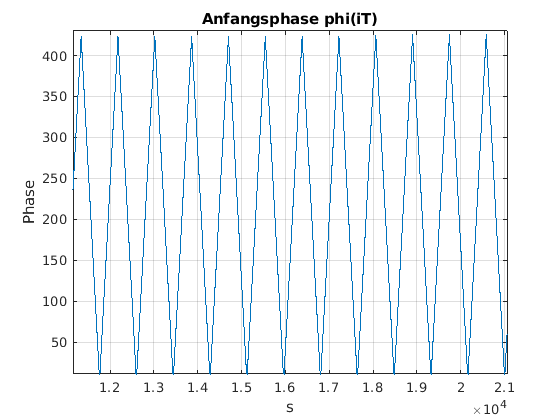

phi_0 = pi;
num_integrator = [0, 1];
den_integrator = [1, -1];
Phi_iT = filter(num_integrator, den_integrator, d_i) + phi_0;
figure(2);
plot(Phi_iT)
grid on
%xlim([0 1000])
title('Anfangsphase phi(iT)')
xlabel(['s'])
ylabel(['Phase'])

xlim([11155 21055])
ylim([11 430])

## Zeitdiskrete CPFSK

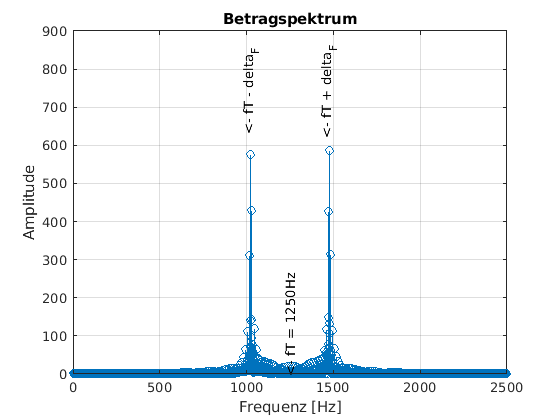

% Bandbreitenabschätzung
% Band > 2*delta_F > 450Hz
delta_F = 225;
% Trägerfrequenz
fT = 1250;
fA = 5000;
% Verstärkung
amp = 0.5;
n = 1:1:fA;

cpfsk_sig = amp * sin(2 * pi * fT * n/fA + 2 * delta_F * pi * Phi_iT(n)/fA + phi_0);
spectrum_sig = abs(fft(cpfsk_sig));
figure(3);
stem(spectrum_sig)
text(fT, 130, '<- fT = 1250Hz', 'HorizontalAlignment', 'center', 'rotation',90)
text(fT-delta_F, 750, '<- fT - delta_F ', 'HorizontalAlignment', 'center', 'rotation',90)
text(fT+delta_F, 750, '<- fT + delta_F ', 'HorizontalAlignment', 'center', 'rotation',90)
title("Betragspektrum")
ylim([0, 900])
xlim([0, 2*fT])
% xlim([idx_start - idx, (idx_start + idx)])
xlabel(['Frequenz [Hz]'])
ylabel(['Amplitude'])
grid on

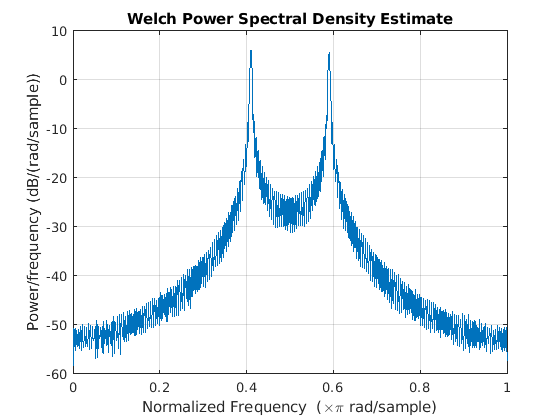

figure(4);
h = spectrum.welch;
pwelch(cpfsk_sig);

## Bandbreite

% Die Bandbreite wird durch den Breich beschrieben, in den 99% der
% Signalenergie fallen.

total_power = 0;
current_power = 0;
idx = 0;
idx_max = round(length(spectrum_sig)/2);
idx_start = idx_max/2; % fA/4

for i = 1:length(spectrum_sig)/2 - 1
    total_power = total_power + abs(spectrum_sig(i))^2 / length(spectrum_sig);
end

N = length(spectrum_sig);

while current_power/total_power < 0.99
    current_power = current_power + abs(spectrum_sig(idx_start - idx))^2 / N;
    current_power = current_power + abs(spectrum_sig(idx_start + idx))^2 / N;
    idx = idx + 1;
end

fprintf("Bandbreite: %dHz\n", ((idx_start + idx) - (idx_start - idx)))

Bandbreite: 536Hz


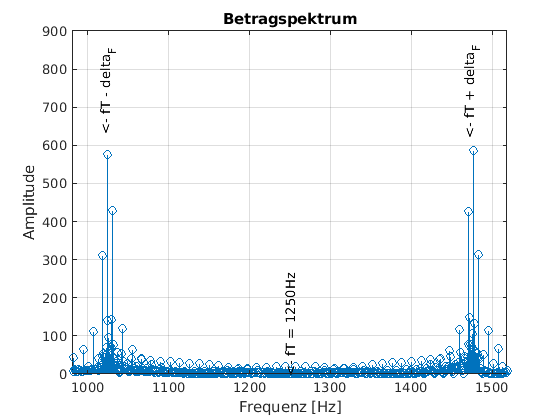


figure(3);
stem(spectrum_sig)
text(fT, 130, '<- fT = 1250Hz', 'HorizontalAlignment', 'center', 'rotation',90)
text(fT-delta_F, 750, '<- fT - delta_F ', 'HorizontalAlignment', 'center', 'rotation',90)
text(fT+delta_F, 750, '<- fT + delta_F ', 'HorizontalAlignment', 'center', 'rotation',90)
title("Betragspektrum")
ylim([0, 900])
xlim([idx_start - idx, (idx_start + idx)])
xlabel(['Frequenz [Hz]'])
ylabel(['Amplitude'])
grid on

## Signalfluss

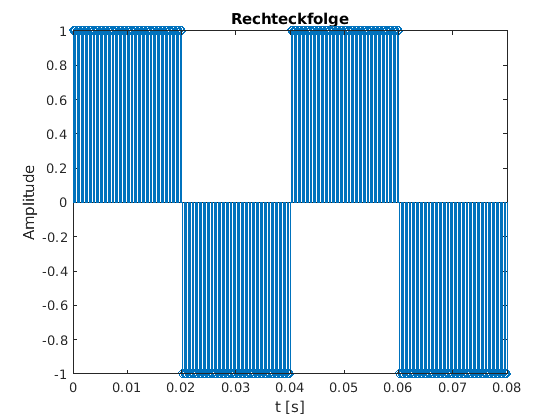

clear all;
close all;

v_max = 0.5;
fA = 4000;
n = 1:1:fA;
fT = fA/4;
fHub = 225;
t = linspace(0, 10, 10*fA + 1);
fSpace = fT - fHub;
fMark = fT + fHub;


size = 1;
cnt = 1;
symbol_t = 0.020;

for i = 0:(1/fA):10
    if i > symbol_t
        size = size * (-1);
        symbol_t = symbol_t + 0.020;
        cnt; % util
    end
    out(cnt) = size;
    cnt = cnt + 1;
end

sqre = out;
stem(t, sqre)
xlim([0, 0.08])
title('Rechteckfolge')
xlabel(['t [s]'])
ylabel(['Amplitude'])

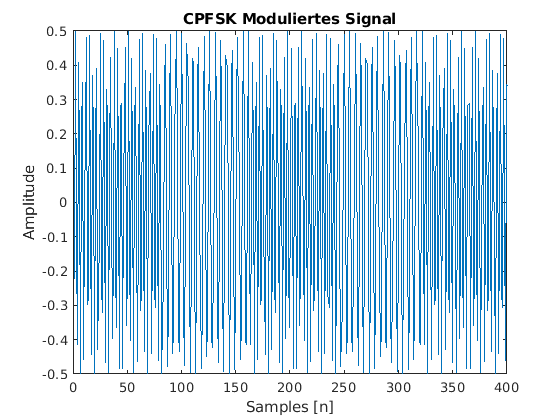


phi_0 = pi;
num_integrator = [0, 1];
den_integrator = [1, -1];

Phi_iT = filter(num_integrator, den_integrator, sqre(1:801)) + phi_0;
cpfsk_sig = v_max * sin(2 * pi * fT * n(1:801)/fA + 2 * fHub * pi * Phi_iT/fA + phi_0);
fn = (-length(n(1:801))/2:(length(n(1:801))-1)/2) * fA/length(n(1:801));

plot(n(1:801), cpfsk_sig)
xlim([0, 400])
title('CPFSK Moduliertes Signal')
xlabel(['Samples [n]'])
ylabel(['Amplitude'])

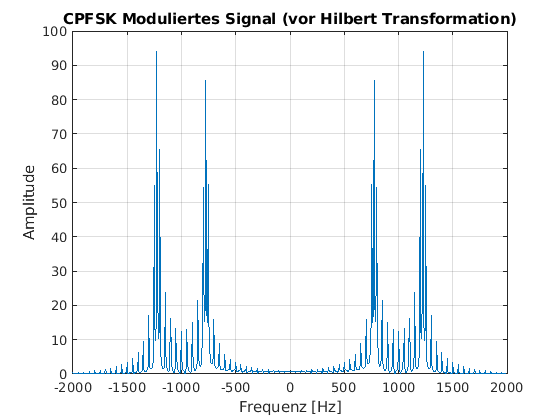


plot(fn, abs(fft(cpfsk_sig)))
title('CPFSK Moduliertes Signal (vor Hilbert Transformation)')
xlabel(['Frequenz [Hz]'])
ylabel(['Amplitude'])
grid on;

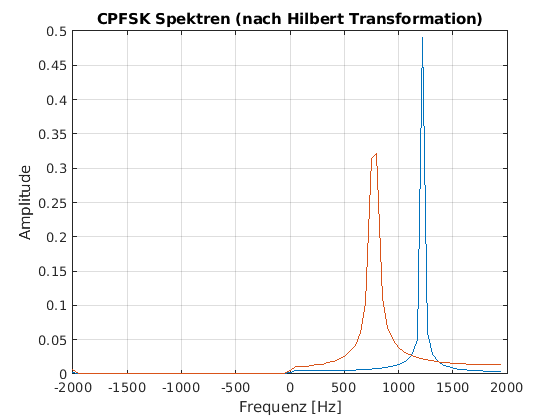



Phi_iT1 = filter(num_integrator, den_integrator, sqre(1:82)) + phi_0;
cpfsk_sig1 = v_max * sin(2 * pi * fT * n(1:82)/fA + 2 * fHub * pi * Phi_iT1/fA + phi_0);
y1 = hilbert(cpfsk_sig1);

Phi_iT0 = filter(num_integrator, den_integrator, sqre(83:162)) + phi_0;
cpfsk_sig0 = v_max * sin(2 * pi * fT * n(83:162)/fA + 2 * fHub * pi * Phi_iT0/fA + phi_0);
y0 = hilbert(cpfsk_sig0);

% Plot
fn0 = (-length(n(1:82))/2:(length(n(1:82))-1)/2) * fA/length(n(1:82));
plot(fn0, abs(fftshift(fft(y1))/length(n(1:82))))
hold on;
fn1 = (-length(n(83:162))/2:(length(n(83:162))-1)/2) * fA/length(n(83:162));
plot(fn1, abs(fftshift(fft(y0))/length(n(83:162))))

title('CPFSK Spektren (nach Hilbert Transformation)')
xlabel(['Frequenz [Hz]'])
ylabel(['Amplitude'])

grid on
hold off;

## Bandpass

[bandpass_2M, fswav] = audioread('CPFSK_modulate_text_ADDA8M12.wav');

Error using audioread>readaudio (line 143)
The filename specified was not found in the MATLAB path.

Error in audioread (line 136)
    [y, Fs] = readaudio (filename, range, datatype);


band(3800, 4800, bandpass_2M, 2019200);
title('Amplitudengang & Phase Bandpass')
xlim([0, 9000])


## Komplexes Kammfilter

N = 3

N = 3

fA_green = 3832;
freq_comb= (-fA_green:fA_green)/fA_green;

compl = (0.175 + 0.985j)

compl = 0.1750 + 0.9850i

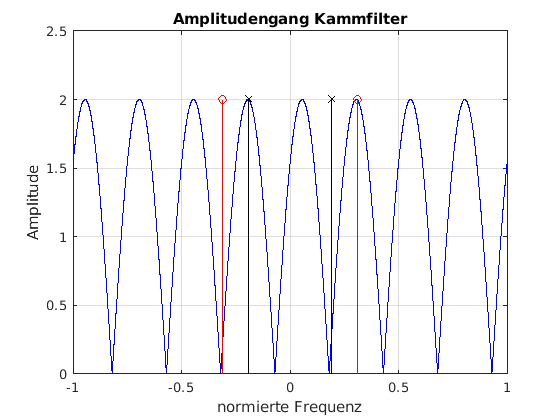

H_comb = freqz([1, zeros(1, N), compl], 1, 2*pi*freq_comb);

figure(4);
plot(freq_comb, abs(H_comb), 'b-')
hold on;
stem(-732/fA_green, 2, 'xk');
stem(-1187/fA_green, 2, 'r');
stem(732/fA_green, 2, 'xk');
stem(1187/fA_green, 2, 'r');
grid on
hold off;
xlabel(['normierte Frequenz'])
ylabel(['Amplitude'])
title('Amplitudengang Kammfilter');